We will now implement our own function to carry out projection of random vectors onto principle components using concepts we learned in class. Assume that the data are zero-mean. Implement the following in your custom function (call it ProjectData.m to avoid conflicts with built-in functions):

NOTE: This question 2 is a continuation of question 1 so I'll be implementing the part from question 1 first and will then be taking my code to continuation of part for question 2

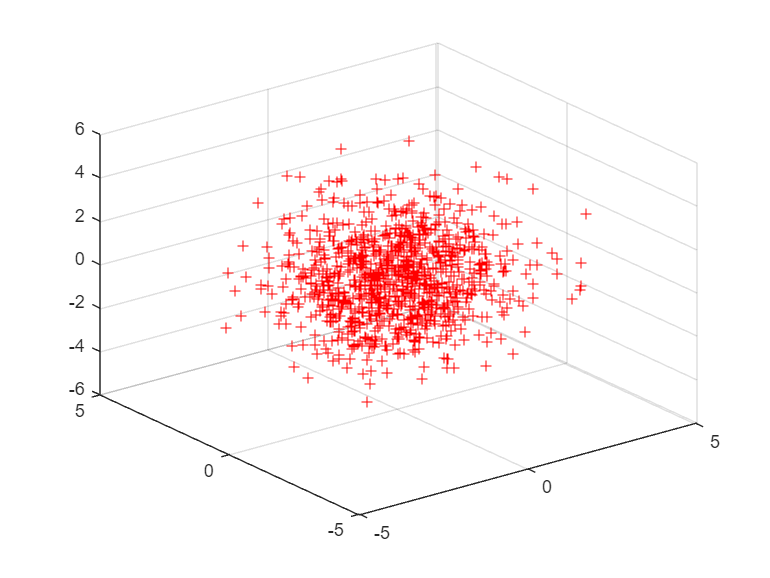

mu1_sb = [0 0 0]; % We have taken mu1_sb vector
Sigma1_sb = [2 0 0; 0 1.5 0; 0 0 2.5]; % We have taken Sigma1_sb Matrix
n1_sb = 1000; % As we have to generate 1000 samples so taken n1_sb=1000
rng('default')  % We have taken default range for reproducibility
R1_sb = mvnrnd(mu1_sb,Sigma1_sb,n1_sb); % Now we have applied mvnrnd function from Statistics and Machine Learning Toolbox of Matlab to our variables, matrix and vector.
figure('Name','3D Scatter Plot for part 1(a) generated using ProjectData function')
scatter3(R1_sb(:,1),R1_sb(:,2),R1_sb(:,3),'+','red') % To plot these random generated 1000 samples from Gaussian distribution we have used scatter3 function of Matlab to visualize distribution in 3D space.

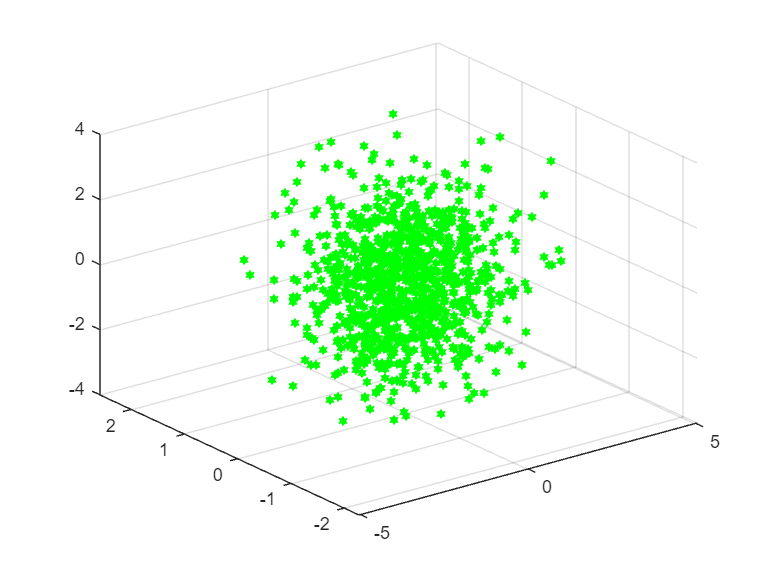

mu2_sb = [0 0 0]; % We have taken mu2_sb vector
Sigma2_sb = [2 0.35 0.62; 0.35 0.5 0.33; 0.62 0.33 1]; % We have taken Sigma2_sb Matrix
n2_sb = 1000; % As we have to generate 1000 samples so taken n2_sb=1000
rng('default')  % We have taken default range for reproducibility
R2_sb = mvnrnd(mu2_sb,Sigma2_sb,n2_sb); % Now we have applied mvnrnd function from Statistics and Machine Learning Toolbox of Matlab to our variables, matrix and vector.
figure('Name','3D Scatter Plot for part 1(b) generated using ProjectData function')
scatter3(R2_sb(:,1),R2_sb(:,2),R2_sb(:,3),'hexagram','green','filled'); % To plot these random generated 1000 samples from Gaussian distribution we have used scatter3 function of Matlab to visualize distribution in 3D space.

Above this we implemented part of question 1. Now we will implement part of question 2.

Parts of question 2

On Applying ProjectData Transformation Function to 1(a)

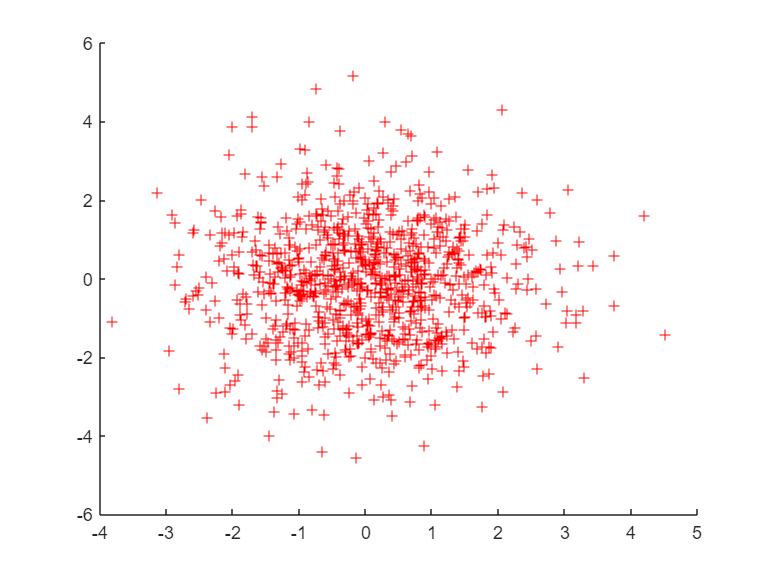

Y=ProjectData(R1_sb);
Y=Y.';
figure('Name','2D Scatter Plot for part 1(a) generated using ProjectData function')
x1_sb=Y(1:1000,1);
y1_sb=Y(1:1000,2);
scatter(x1_sb,y1_sb,'+','red');

On Applying ProjectData Transformation Function to 1(b)

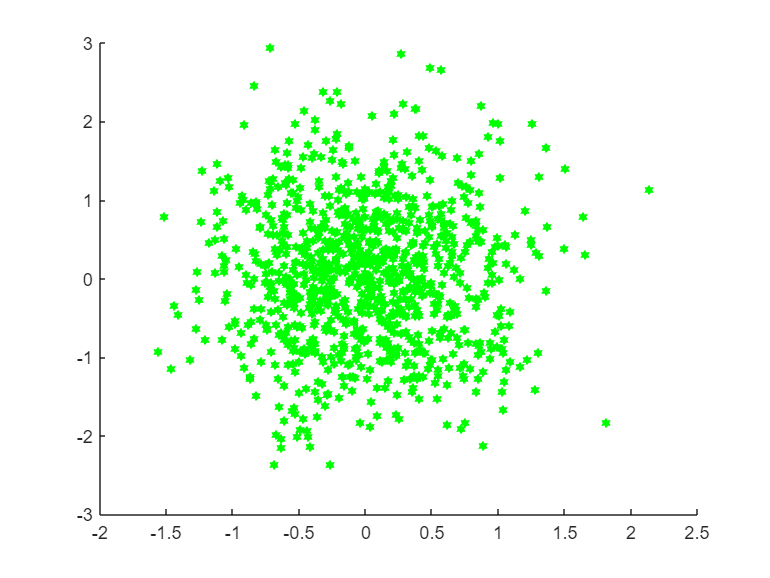

Y=ProjectData(R2_sb);
Y=Y.';
figure('Name','2D Scatter Plot for part 1(b) generated using ProjectData function')
x2_sb=Y(1:1000,1);
y2_sb=Y(1:1000,2);
scatter(x2_sb,y2_sb,'hexagram','green','filled');

Now we will implement our ProjectData.m function as per the guidance provided in the Question:

- Assume that the input to the function is a data matrix, X; of size d x n, comprising of n data samples, each a point (vector) in the d- dimensional Euclidean space, Rd. The output of the function will be a data matrix Y of size d2 x n, where d2 <<d

- Estimate the Covariance Matrix of the Data (you may use the built-in Matlab function,cov for this).

- Perform the eigen-decomposition of the covariance matrix (you may use the built-in Matlab function, eig for this). The eigenvector matrix you will get out of this is of size d x d.

- Ensure your eigenvectors and eigenvalues are sorted in descending order of eigenvalues - i.e., the first eigenvector corresponds to the largest eigenvalue, and so on...

- Your projection (transformation) matrix T is then obtained by selecting the first d2 columns of the eigenvector matrix, resulting in a transformation matrix T of size d x d2

- The transformation T : Rd -> Rd2 can be used to project data in the d-dimensional Euclidean space to a (lower) d2 dimensional subspace by the simple matrix operation Y = T'X.

NOTE: Instead of creating separate ProjectData.m function file in Matlab I have implemented this function in the code file to avoid importing the function and calling it externally each time we run our code.

function Y = ProjectData(X) % Input to the ProjectData function is data matrix X and output is data matrix Y.
covarMAT = cov(X); % Estimating the Covariance Matrix of the input Data matrix X using in-built function cov() of Matlab.
[P, eigMAT] = eig(covarMAT); % Performing the eigen-decomposition of the covariance matrix covarMAT using in-built function eig() of Matlab.
eigMAT = sort(eigMAT,'descend'); % Keeping eigenvectors and eigenvalues sorted in descending order of eigenvalues using in-built function sort() of Matlab.
TrPoseMAT = P(:, 1:2); % Obtaining matrix TrPoseMAT by selecting the first d2 columns of the eigenvector matrix, resulting in the transformation matrix TrPoseMAT �
Y=TrPoseMAT.'*X.'; % Using the transformation to project data in the d-dimensional Euclidean space to a (lower) d2 dimensional subspace by the simple matrix operation Y = TrPoseMAT'X.
end